# **最短路径**

**可以使用Dijkstra算法，Matlab中使用graphshortestpath函数**

% sparse生成稀疏矩阵（除了注明的，其他都是0）
% sparse里第一个矩阵和第二个矩阵相同位置的元素值就是非零元素的索引
W = [10,5,2,1,4,6,7,3,9,2] % 每条边的权重

W =     10     5     2     1     4     6     7     3     9     2


DG = sparse([1,1,2,2,3,4,4,5,5,5], ...
            [2,5,5,3,4,3,1,2,3,4],W)

DG =    (4,1)        7
   (1,2)       10
   (5,2)        3
   (2,3)        1
   (4,3)        6
   (5,3)        9
   (3,4)        4
   (5,4)        2
   (1,5)        5
   (2,5)        2


% 比如第一个索引，表示从点1到点2的权重是10，以此类推

% dist最短路径的值，path节点顺序，pred到每一个节点的最短路径的终点前一个节点
[dist, path, pred] = graphshortestpath(DG, 1, 3);

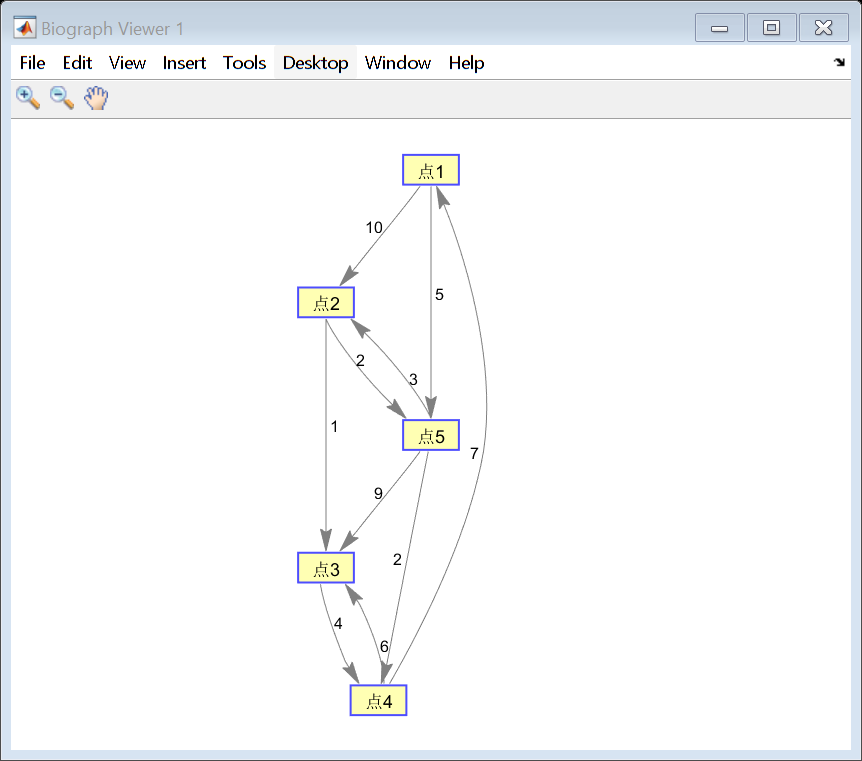

points_name = ["点1","点2","点3","点4","点5"];
% 作图
% 参数options
view(biograph(DG, points_name, 'showWeights', 'on'));